%function LightSensor(robotName, ldrPin)

% System reset
clc; clear;
clear myDroid; % Use a consistent name for this device throughout the code.
% add clear myDroid at the end of code
myDroid = arduino('COM6','Uno','Libraries',{'Ultrasonic','Servo', 'I2C'}); % adds libraries to support other devices

% Configure pins for ultrasonic sensor
    usEchoPin = 'A1'; % pin connected to ultrasonic echo
        configurePin(myDroid,usEchoPin,'Ultrasonic'); % Ultrasonic echo
    usTriggerPin = 'A0'; % pin connected to ultrasonic trigger
        configurePin(myDroid,usTriggerPin,'Ultrasonic'); % Ultrasonic trigger   
% Configure pins for light sensor
    ldrPin = 'A4';
        configurePin(myDroid,ldrPin,'AnalogInput');
    ldrVolt = readVoltage(myDroid, ldrPin);
     fprintf("Voltage is at %f", ldrVolt)

Voltage is at 0.767351

    
% Output format switched to double to simplify calculations and display
    frontUSsensor = ultrasonic(myDroid,usTriggerPin,usEchoPin,'OutputFormat','double' );
% Assign and configure pins for servo control
frontServoPin = 'D10';
configurePin(myDroid, frontServoPin, 'Servo')

% Set Servo Characteristics - Pulse Duration Values - servo dependent.
rotMinPulse = 500* 10^-6; % minimum pulse width
rotMaxPulse = 2400* 10^-6; % maximum pulse width
    
% Servo Object Setup: Servo pins and pulse characteristics assigned to device
frontScanServo = servo(myDroid, frontServoPin, 'MinPulseDuration', rotMinPulse,...
    'MaxPulseDuration', rotMaxPulse);
% Control Example 
    % Set to Center and reattach head
    centerValue = 0.5;
    writePosition(frontScanServo, centerValue)
    startPosition = readPosition(frontScanServo)

startPosition = 0.5000

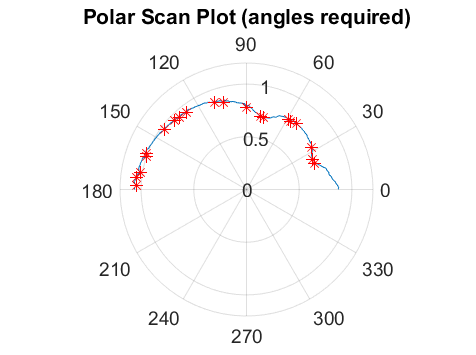

% Capture user input for desired postion 
   desiredPosition = -90;
   
    % Convert angle to 0-1
   desiredPosition = round(-1/180 * desiredPosition + centerValue,3);
    % Send 1st position,
    writePosition(frontScanServo, desiredPosition)

    % Check position, show on screen
    checkPosition = readPosition(frontScanServo);
    % Return to center
    pause(2)

angleArray = zeros(1,181);
degArray = zeros(1,181);
lightArray = zeros(1,181);


for i = -90:90
    j = round(-1/180 * i + centerValue,3);
    writePosition(frontScanServo, j)
    ldrVolt = readVoltage(myDroid, ldrPin);
    p = i + 91; % Sets start of array values (can't be a negative num/0)
    angleArray(p) = j;
    degArray(p) = i + 90;
    lightArray(p) = ldrVolt;
  
    %fprintf('\nCurrent distance is %0.3f m, %0.1f cm or %0.1f inches.\n',distance,distance*100,distance*39.37);
    pause(0.0015)
end

dr = deg2rad(degArray(1,:));
LA = lightArray(1,:);

% subplot(1,2,2)
TF = islocalmin(LA);
polarplot(dr, LA, dr(TF), LA(TF), 'r*')
title('Polar Scan Plot (angles required)')


for i  = 1:180
    if TF(i) == 0
        lightArray(i) = 100;
    end
end

lightPoint = zeros(1,4);
turnAngle = zeros(1,4);

for i = 1:4
    lightPoint(i) = min(lightArray)
    lightTarget = min(lightArray);
    [x,y] = find(lightArray == lightTarget);
    a = x(1,1);
    b = y(1,1);
    lightArray(a,b) = 100;
    turnAngle(i) = angleArray(a,b);
end

lightPoint =     0.6891         0         0         0


lightPoint =     0.6891    0.6940         0         0


lightPoint =     0.6891    0.6940    0.6989         0


lightPoint =     0.6891    0.6940    0.6989    0.7087



tHeDoRe = sum(turnAngle)/4

tHeDoRe = 0.7208


writePosition(frontScanServo,tHeDoRe)

tHeReAlDoRE = 180 - round(tHeDoRe * 180,1)

tHeReAlDoRE = 129.7000



%end